t =    -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000


t =    -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000


t =    -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000


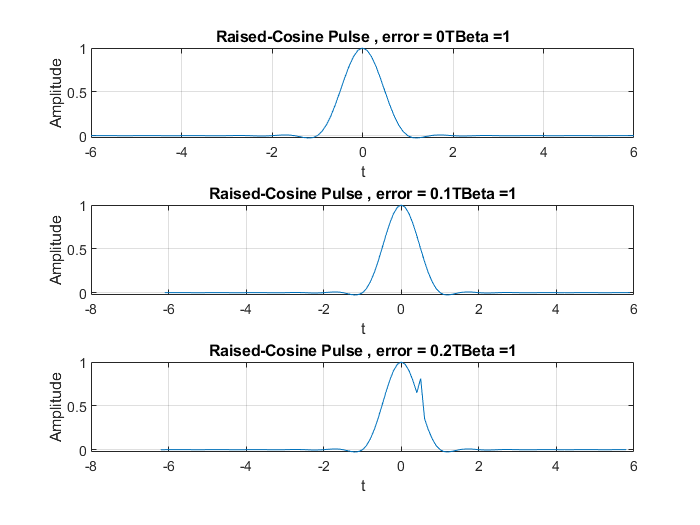

% Section 1: Raised-Cosine Generation
T = 1;
Fs = 10;
B = 1;
sampling_error  = [0,0.1*T,0.2*T];
start = -6*T;
ending = 6*T;
len = (ending - start)*Fs + 1;
t = zeros(3, len);
pulse = zeros(3, len);
for i = 1:3
    [t(i,:), pulse(i,:)] = RC_pulse(T, Fs, B, sampling_error(i), start, ending);
    subplot(3,1,i);
    plot (t(i,:),pulse(i,:));
    title("Raised-Cosine Pulse , error = " + sampling_error(i)/T + "T"+"Beta =" + B);
    xlabel('t');
    ylabel('Amplitude');
    grid on;
end

% Section 2: Signal Generation
N = 10e5;
random_bits = randi([0,1], 1, N);

symbols = zeros(1,length(random_bits));

for i=1:length(random_bits)
    if ( random_bits(1,i) == 1 )
        symbols(1, i) = 1 ;
    else
        symbols(1, i) = -1;
    end
end

upsampled_symbols = upsample(symbols, T*Fs);
upsampled_symbols = upsampled_symbols(1 : (end - ( T*Fs -1)));

transmitted_signal = zeros(3, (length(upsampled_symbols)+length(pulse)-1));
for i = 1:3
transmitted_signal(i,:) = conv(upsampled_symbols, pulse(i,:)) ;
end

% Section 3: Noise Generation and AWGN Channel Modeling:

SNR_dB = 0:10;
Eb = 1;
SNR = zeros(1,length(SNR_dB)) ;

for i=1:length(SNR)
    SNR(1,i) = (10)^(SNR_dB(1,i)/10) ;
end

eta = zeros(1,length(SNR));
for i=1:length(eta)
    eta(1,i) = Eb/(SNR(1,i)) ;
end

noise = randn(1,length(transmitted_signal));
noise = diag(sqrt(eta./2))*repmat(noise,11,1);

received_signal1 = repmat(transmitted_signal(1,:),11,1)+ noise;
received_signal2 = repmat(transmitted_signal(2,:),11,1)+ noise;
received_signal3 = repmat(transmitted_signal(3,:),11,1)+ noise;

% Section 4: Symbol Detection

L = T * Fs;
T_sampling = 6*L + 1 : L : (N+6-1)*L + 1 ;

samples1 = received_signal1(:,T_sampling);
samples2 = received_signal2(:,T_sampling);
samples3 = received_signal3(:,T_sampling);

detected_symbols1 = symbol_detection(samples1 ,N);
detected_symbols2 = symbol_detection(samples2 ,N);
detected_symbols3 = symbol_detection(samples3 ,N);


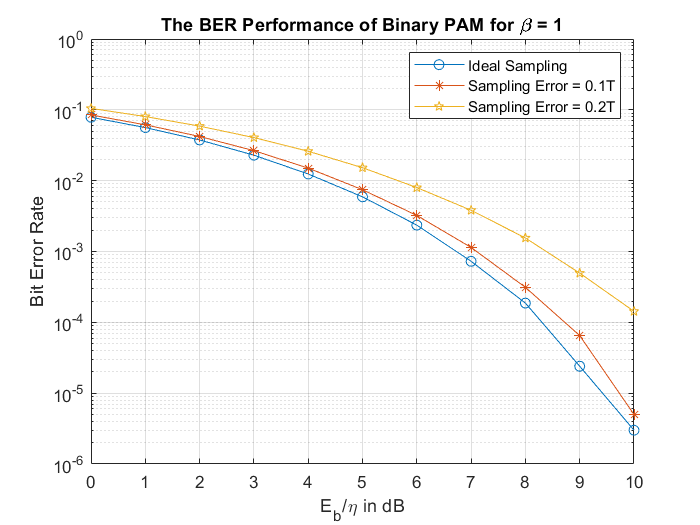

% Section 5: Error Probability Calculation:

repeated_symbols = repmat(symbols,11,1);

Pe1 = Error_probability(repeated_symbols, detected_symbols1, N);
Pe2 = Error_probability(repeated_symbols, detected_symbols2, N);
Pe3 = Error_probability(repeated_symbols, detected_symbols3, N);

figure
p = [.5 0 .5];
semilogy(SNR_dB, Pe1 ,'-o' ,SNR_dB ,Pe2,'-*' ,SNR_dB ,Pe3,'-p')
grid on
title("{The BER Performance of Binary PAM for \beta = " + B + "}")
xlabel('{E_b}/\eta in dB');
ylabel('Bit Error Rate')
legend('Ideal Sampling','Sampling Error = 0.1T','Sampling Error = 0.2T')